load("case_1.mat");

1)

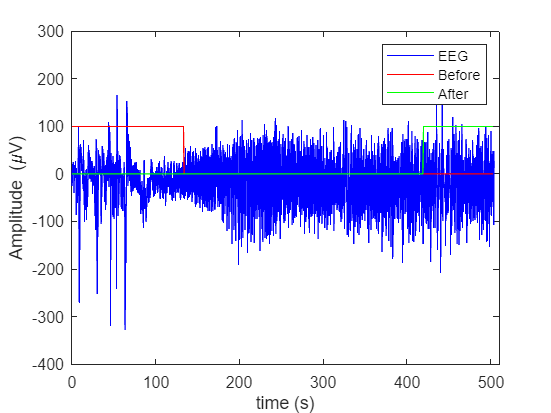

figure
plot(eeg_time,eeg_ch,"b-")
hold on
plot(annot_time,100*before,"r-")
hold on
plot(annot_time,100*after,"g-")
legend("EEG","Before","After")
xlabel("time (s)")
ylabel("Amplitude (\muV)")
xlim([0 510])
hold off

%anesthesia period between 133s-420s

2)

measure_time = eeg_time(64512);
samples = 64512;
sample_time = measure_time/samples;
fs_eeg = round(1/sample_time,0)

fs_eeg = 128

Sampling frequency is 128Hz

3)

%FIR highpass filter with cutoff frequency 0.5Hz
N = 120

N = 120

fc = 0.5/(fs_eeg/2) %normalized

fc = 0.0078

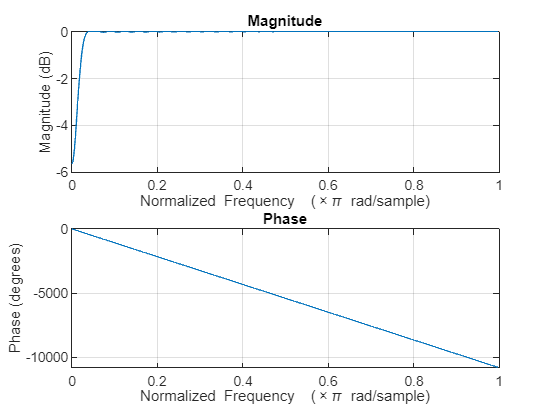


b = fir1(N, fc, "high");
figure
freqz(b)

eeg_f = filter(b,1,eeg_ch);

4)

figure
subplot(2,1,1)
plot(eeg_time,eeg_ch,"b-")
title("Original EEG")
ylabel("Amplitude (\muV)")
xlabel("time (s)")
xlim([0 510])
subplot(2,1,2)
plot(eeg_time,eeg_f,"b-")'

ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0080 0.0160 0.0230 0.0310 0.0390 0.0470 0.0550 0.0630 0.0700 0.0780 0.0860 0.0940 0.1020 0.1090 0.1170 0.1250 0.1330 0.1410 0.1480 0.1560 0.1640 0.1720 0.1800 0.1870 0.1950 0.2030 0.2110 0.2190 0.2270 0.2340 … ] (1×64512 double)
              YData: [8.0308e-04 8.2089e-04 2.7554e-05 7.7223e-04 0.0059 0.0164 0.0233 0.0267 0.0296 0.0302 0.0312 0.0339 0.0364 0.0420 0.0470 0.0491 0.0554 0.0663 0.0771 0.0887 0.0973 0.1031 0.1106 0.1168 0.1233 0.1358 0.1501 0.1659 … ] (1×64512 double)

  Show all pro

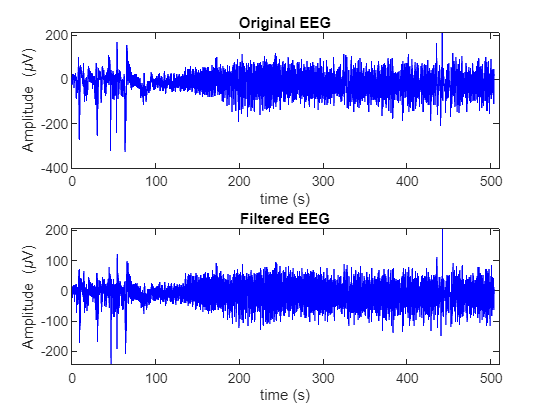

title("Filtered EEG")
ylabel("Amplitude (\muV)")
xlabel("time (s)")
xlim([0 510])


%Affect to the awaking parts, peaks are not as high as an original signal


6)

[H,H_t] = entropy_eeg(eeg_f,fs_eeg);

7)

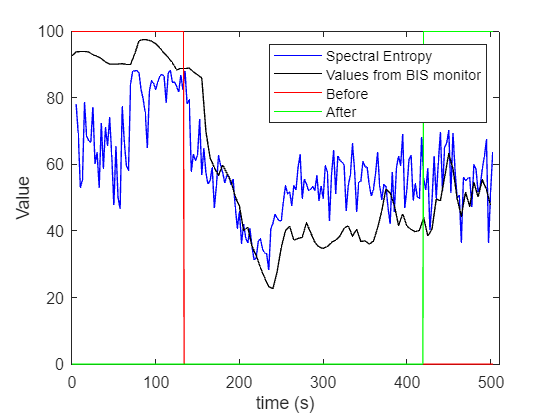

figure
plot(H_t,100*H,"b-")
hold on
plot(bis_time,bis_ch,"k-")
hold on
plot(annot_time,100*before,"r-")
hold on
plot(annot_time,100*after,"g-")
hold off
xlabel("time (s)")
ylabel("Value")
legend("Spectral Entropy", "Values from BIS monitor","Before","After")
xlim([0 510])